clear all;clc;close all;
opts = delimitedTextImportOptions("NumVariables", 24);
% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";
% Specify column names and types
opts.VariableNames = ["Área", "Longitud eje mayor", "Longitud eje menor", "Área convexa","Circularidad", "Perímetro", "Distancia mínima entre núcleos", "Varianza área","Varianza área convexa","Varianza circularidad","Varianza perímetro","Varianza longitud eje mayor","Ratio medio distancia ejes","Porcentaje de núcleos","Varianza de la distancia del eje menor","Compactabilidad de núcleos","Distancia media entre núcleos","Varianza distancia entre núcleos","Varianza del ratio de distancia ejes","Contraste","Correlación", "Homogenidad","Energía","Tipo de cáncer"];
opts.VariableTypes = ["double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","categorical"];
% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
A = struct2cell(load("5_DCIS.mat"));
A = A{1,1};
B = struct2cell(load("6_IC.mat"));
B = B{1,1};
taula = [A; B];
[UniqueData,Repeatedpoints]=repeated_data(taula);%cambiar nombre de la función

nRepeatedPoints =      0


Uniquedata = 166×24 table
       Infomean1           Infomean2           Infomean3           Infomean4            Infomean5           Infomean6             Infomean7             Infomean8           Infomean9            Infomean10           Infomean11          Infomean12          Infomean13          Infomean14           Infomean15          Infomean16           Infomean17            Infomean18           Infomean19           Infomean20           Infomean21           Infomean22            Infomean23        Var24
    ________________    ________________    

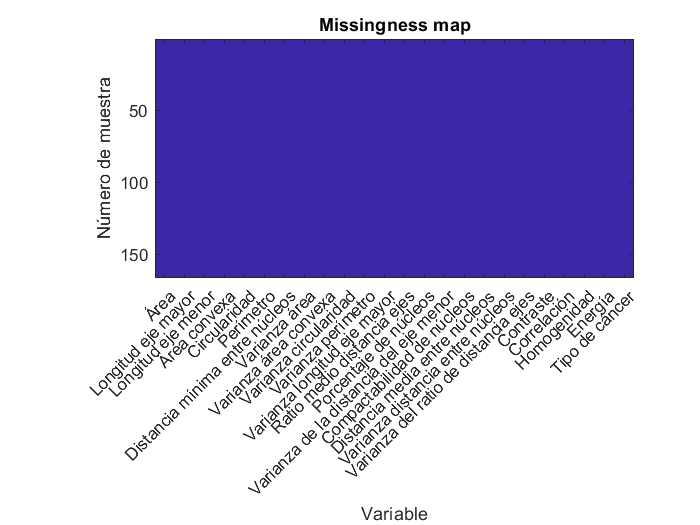

Nombres = opts.VariableNames;
Nombres;
PreprocessedDdata = processed(UniqueData);
imagesc(ismissing(PreprocessedDdata,{'' '.' 'NA' NaN -99}))
xticks(1:length(Nombres));
xticklabels(Nombres);
xtickangle(45)
title('Missingness map');
xlabel('Variable');
ylabel('Número de muestra')

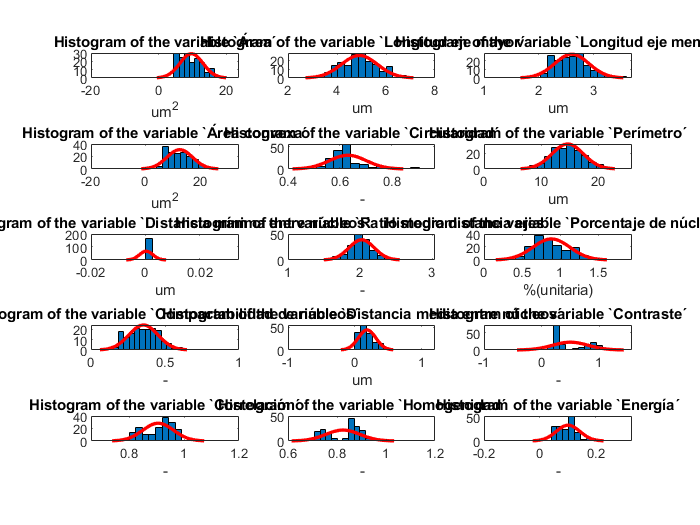


a=[1:7,13,14,16,17,20:23];
b=[24];
c=b;
units= ["um^2","um","um","um^2","-","um","um","-v","-v","-v","-v","-v","-","%(unitaria)","-v","-","um","-v","-v","-","-","-","-"];
[dataN,response_var,independent_vars,categorical_vars] =inconsistent_data(PreprocessedDdata,a,b,c);

for i=1:length(a)
    subplot(5,3,i)
    h = histfit(independent_vars(:,i));
    maximo(i) = max(h(2).XData);
    minimo(i) = min(h(2).XData);
    if minimo(i)<0
        minimo(i) = 0;
    end
    %histfit(independent_vars(:,i))
    title(strcat('Histogram of the variable `',Nombres{a(i)},'´'));
    xlabel(units{a(i)});
end

l=1;

for p=1:height(dataN)
    if independent_vars(p,1:width(independent_vars))>minimo(1:width(independent_vars)) & independent_vars(p,1:width(independent_vars))<maximo(1:width(independent_vars))
        dataN1(l,:)=(dataN(p,:));
        l= l+1;
    end
end
independent_vars1 =  table2array(dataN1(:,a));
% independent_vars1 = table2array(independent_vars1);
for i=1:15
    fprintf('Mean value for variable %s is %.2f\n', Nombres{a(i)},mean(independent_vars1(:,i)));%FALTA TRADUCIR
    fprintf('Median for variable %s is %.2f\n', Nombres{a(i)},median(independent_vars1(:,i)));
    fprintf('Mode for variable %s is %.2f\n', Nombres{a(i)},mode(round(independent_vars1(:,i),1)));
    fprintf('Max. value for variable %s is %.2f\n', Nombres{a(i)},max(independent_vars1(:,i)));
    fprintf('Min. value for variable %s is %.2f\n', Nombres{a(i)},min(independent_vars1(:,i)));
    fprintf('Standard deviation for variable %s is %.2f\n \n', Nombres{a(i)},std(independent_vars1(:,i)));
end

Mean value for variable Área is 9.52


Median for variable Área is 8.78


Mode for variable Área is 5.70


Max. value for variable Área is 18.51


Min. value for variable Área is 5.27


Standard deviation for variable Área is 3.14
 


Mean value for variable Longitud eje mayor is 4.90


Median for variable Longitud eje mayor is 4.90


Mode for variable Longitud eje mayor is 4.60


Max. value for variable Longitud eje mayor is 6.72


Min. value for variable Longitud eje mayor is 3.65


Standard deviation for variable Longitud eje mayor is 0.66
 


Mean value for variable Longitud eje menor is 2.59


Median for variable Longitud eje menor is 2.59


Mode for variable Longitud eje menor is 2.80


Max. value for variable Longitud eje menor is 3.36


Min. value for variable Longitud eje menor is 2.10


Standard deviation for variable Longitud eje menor is 0.29
 


Mean value for variable Área convexa is 12.42


Median for variable Área convexa is 11.46


Mode for variable Área convexa is 7.70


Max. value for variable Área convexa is 24.66


Min. value for variable Área convexa is 6.42


Standard deviation for variable Área convexa is 4.26
 


Mean value for variable Circularidad is 0.63


Median for variable Circularidad is 0.62


Mode for variable Circularidad is 0.60


Max. value for variable Circularidad is 0.83


Min. value for variable Circularidad is 0.53


Standard deviation for variable Circularidad is 0.06
 


Mean value for variable Perímetro is 14.61


Median for variable Perímetro is 14.51


Mode for variable Perímetro is 12.70


Max. value for variable Perímetro is 20.95


Min. value for variable Perímetro is 9.66


Standard deviation for variable Perímetro is 2.44
 


Mean value for variable Distancia mínima entre núcleos is 0.00


Median for variable Distancia mínima entre núcleos is 0.00


Mode for variable Distancia mínima entre núcleos is 0.00


Max. value for variable Distancia mínima entre núcleos is 0.00


Min. value for variable Distancia mínima entre núcleos is 0.00


Standard deviation for variable Distancia mínima entre núcleos is 0.00
 


Mean value for variable Ratio medio distancia ejes is 2.02


Median for variable Ratio medio distancia ejes is 2.01


Mode for variable Ratio medio distancia ejes is 2.00


Max. value for variable Ratio medio distancia ejes is 2.46


Min. value for variable Ratio medio distancia ejes is 1.70


Standard deviation for variable Ratio medio distancia ejes is 0.15
 


Mean value for variable Porcentaje de núcleos is 0.88


Median for variable Porcentaje de núcleos is 0.86


Mode for variable Porcentaje de núcleos is 0.70


Max. value for variable Porcentaje de núcleos is 1.37


Min. value for variable Porcentaje de núcleos is 0.44


Standard deviation for variable Porcentaje de núcleos is 0.21
 


Mean value for variable Compactabilidad de núcleos is 0.35


Median for variable Compactabilidad de núcleos is 0.35


Mode for variable Compactabilidad de núcleos is 0.40


Max. value for variable Compactabilidad de núcleos is 0.59


Min. value for variable Compactabilidad de núcleos is 0.17


Standard deviation for variable Compactabilidad de núcleos is 0.10
 


Mean value for variable Distancia media entre núcleos is 0.17


Median for variable Distancia media entre núcleos is 0.15


Mode for variable Distancia media entre núcleos is 0.10


Max. value for variable Distancia media entre núcleos is 0.45


Min. value for variable Distancia media entre núcleos is 0.03


Standard deviation for variable Distancia media entre núcleos is 0.10
 


Mean value for variable Contraste is 0.49


Median for variable Contraste is 0.31


Mode for variable Contraste is 0.30


Max. value for variable Contraste is 1.06


Min. value for variable Contraste is 0.16


Standard deviation for variable Contraste is 0.29
 


Mean value for variable Correlación is 0.91


Median for variable Correlación is 0.92


Mode for variable Correlación is 0.90


Max. value for variable Correlación is 0.98


Min. value for variable Correlación is 0.75


Standard deviation for variable Correlación is 0.05
 


Mean value for variable Homogenidad is 0.82


Median for variable Homogenidad is 0.86


Mode for variable Homogenidad is 0.90


Max. value for variable Homogenidad is 0.92


Min. value for variable Homogenidad is 0.70


Standard deviation for variable Homogenidad is 0.07
 


Mean value for variable Energía is 0.10


Median for variable Energía is 0.10


Mode for variable Energía is 0.10


Max. value for variable Energía is 0.19


Min. value for variable Energía is 0.05


Standard deviation for variable Energía is 0.03
 


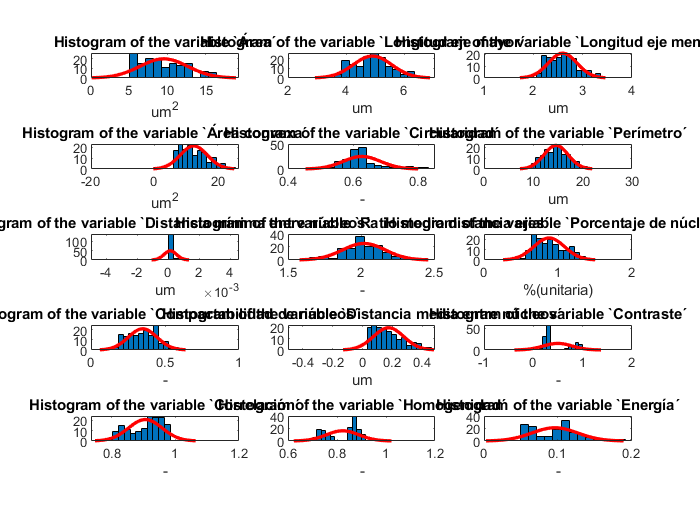

for i=1:length(a)
    subplot(5,3,i)
    h = histfit(independent_vars1(:,i));
    histfit(independent_vars1(:,i))
    title(strcat('Histogram of the variable `',Nombres{a(i)},'´'));
    xlabel(units{a(i)});
end

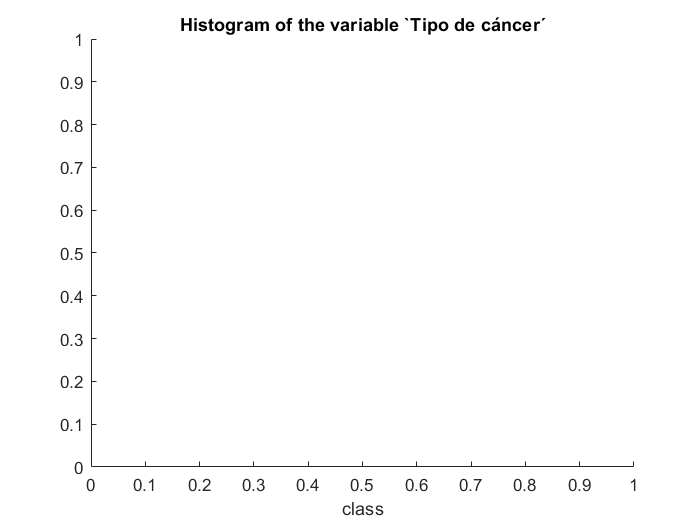

figure ()
%corrplot(dataN1(:,1:23));
A=categorical_vars(:,1);
B=removecats(A);
%hist(categorical_vars(:,1),(categories(B)))
title(strcat('Histogram of the variable `',Nombres{b(1)},'´'));
xlabel('class');

dataN2=(dataN1);
%dataN2=table2array(dataN2);
for i=1:23
    dataN2(:,i)=array2table(rescale(table2array(dataN1(:,i))));
end

dataN3=[]


dataN3 =

     []



dataN4=[]


dataN4 =

     []




f=24;
a1=1;
b1=1;

[m1,n1]= size(dataN1);
for i = 1:m1
    if table2array(dataN1(i,f)) == "DCIS"
        dataN3 = [dataN3 i];
        a1=a1+1;
    end
    if  table2array(dataN1(i,f)) == "IC"
        dataN4 = [dataN4 i];
        b1=b1+1;
    end
end

taula_DCIS = dataN1(transpose(dataN3),:); 
taula_IC = dataN1(transpose(dataN4),:);
DataAnova = [taula_DCIS(:,1:23); taula_IC(:,1:23)];
DataAnova = rows2vars(DataAnova);
DataAnova(:,1)=[];
DataAnova = table2array(DataAnova);
% GroupsAnova = [rows2vars(taula_N(:,24)) rows2vars(taula_PB(:,24)) rows2vars(taula_UDH(:,24)) rows2vars(taula_FEA(:,24)) rows2vars(taula_ADH(:,24))  rows2vars(taula_DCIS(:,24)) rows2vars(taula_IC(:,24))];
optA=rows2vars(taula_DCIS(:,24));
optB=rows2vars((taula_IC(:,24)));
A1=ones(1,width(optA)-1);
B1=2.*ones(1,width(optB)-1);
GroupsAnova=[A1 B1];
for a = 1:23
    [H1(a),p1(a)] = ttest2(transpose(table2array(taula_DCIS(:,a))),transpose(table2array(taula_IC(:,a))));
end

idx = fscmrmr(dataN2,"Tipo de cáncer");

data_corr = dataN2;
data1 = dataN2;
data_todo = dataN2;
%data_corr(:, [1,2,3,4,6,8,10,12,13,22]) = [];
data1(:, [1,4,5,6,9,11,12,17,21,22,23]) = [];
data_todo(:, [1,4,6,9,11,21,22]) = [];
k = 5;
%cvpt = cvpartition(data_corr.("Tipo de cáncer"),"KFold",k);
cvpt1 = cvpartition(data1.("Tipo de cáncer"),"KFold",k);
cvpt2 = cvpartition(data_todo.("Tipo de cáncer"),"KFold",k);

## KNN

mdl = fitcknn(data1, "Tipo de cáncer","NumNeighbors",2,"CVPartition",cvpt1, 'DistanceWeight', 'inverse');
mdlLoss = kfoldLoss(mdl) %This row will print the mean Loss value. 

mdlLoss =    0.145695364238411


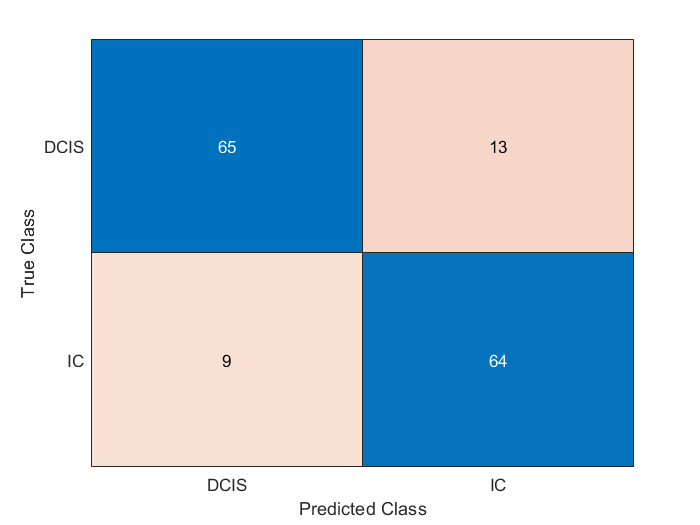

mdlLoss = kfoldLoss(mdl, 'Mode', 'Individual'); %This row will compute the Loss for each Cross-Validation fold. This is interesting for the final comparisons. 
[yFit,sFit] = kfoldPredict(mdl);
confusionchart(data1.("Tipo de cáncer"),yFit)


mdl1 = fitcknn(data_todo, "Tipo de cáncer","NumNeighbors",2,"CVPartition",cvpt2, 'DistanceWeight', 'inverse');
mdlLoss1 = kfoldLoss(mdl1) %This row will print the mean Loss value. 

mdlLoss1 =    0.119205298013245


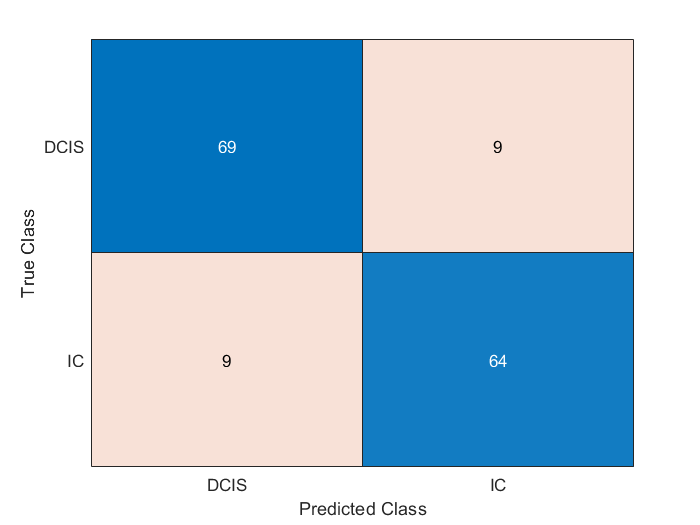

mdlLoss1 = kfoldLoss(mdl1, 'Mode', 'Individual'); %This row will compute the Loss for each Cross-Validation fold. This is interesting for the final comparisons. 
[yFit,sFit] = kfoldPredict(mdl1);
confusionchart(data_todo.("Tipo de cáncer"),yFit)

## Classification trees NO

mdlTree = fitctree(data1, "Tipo de cáncer","CVPartition",cvpt1);
mdlTreeLoss = kfoldLoss(mdlTree)

mdlTreeLoss =    0.251655629139073


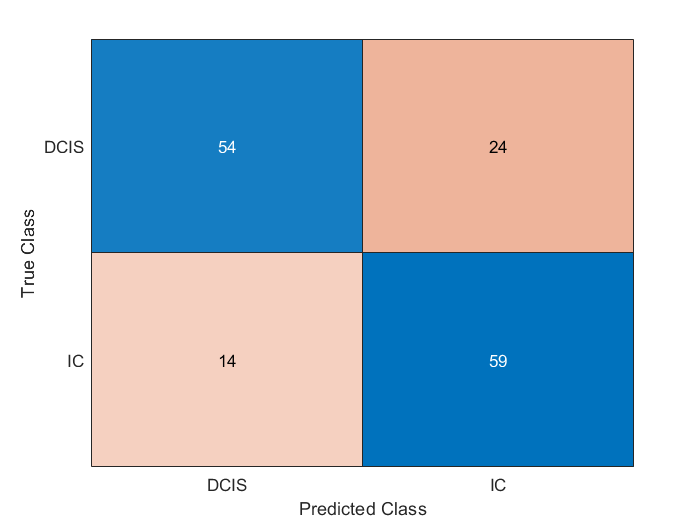

mdlTreeLoss = kfoldLoss(mdlTree, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlTree);
confusionchart(data1.("Tipo de cáncer"),yFit)


mdlTree1 = fitctree(data_todo, "Tipo de cáncer","CVPartition",cvpt2);
mdlTreeLoss1 = kfoldLoss(mdlTree1)

mdlTreeLoss1 =    0.238410596026490


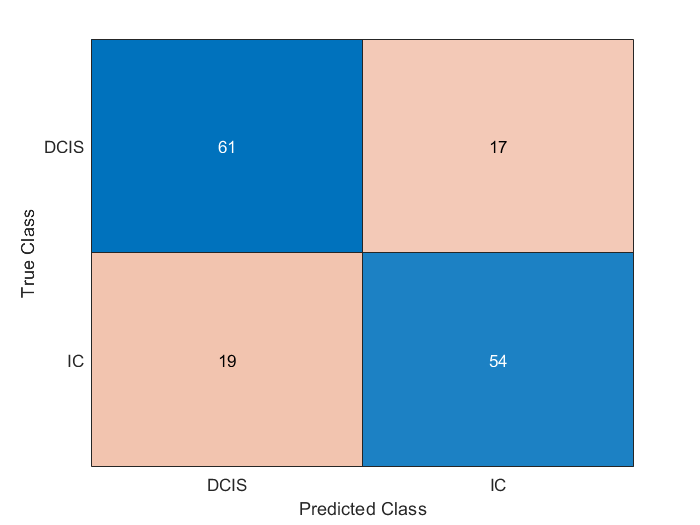

mdlTreeLoss1 = kfoldLoss(mdlTree1, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlTree1);
confusionchart(data_todo.("Tipo de cáncer"),yFit)

## Naive Bayes NO

mdlNB = fitcnb(data1, "Tipo de cáncer","CVPartition",cvpt1);
mdlNBLoss = kfoldLoss(mdlNB)

mdlNBLoss =    0.304635761589404


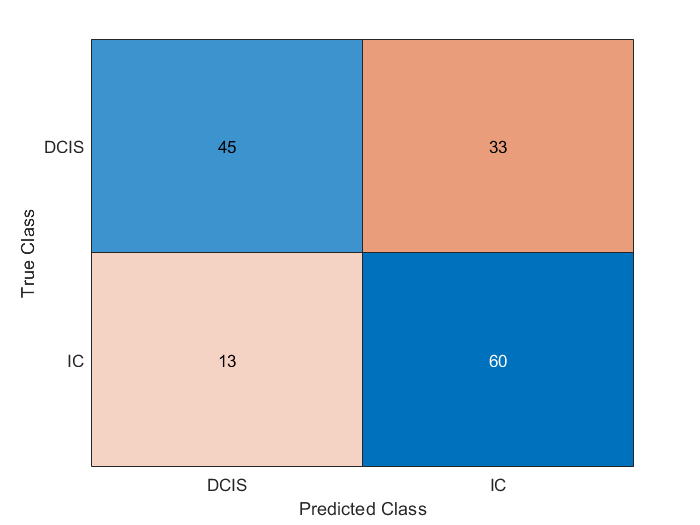

mdlNBLoss = kfoldLoss(mdlNB, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlNB);
confusionchart(data1.("Tipo de cáncer"),yFit)


mdlNB1 = fitcnb(data_todo, "Tipo de cáncer","CVPartition",cvpt2);
mdlNBLoss1 = kfoldLoss(mdlNB1)

mdlNBLoss1 =    0.291390728476821


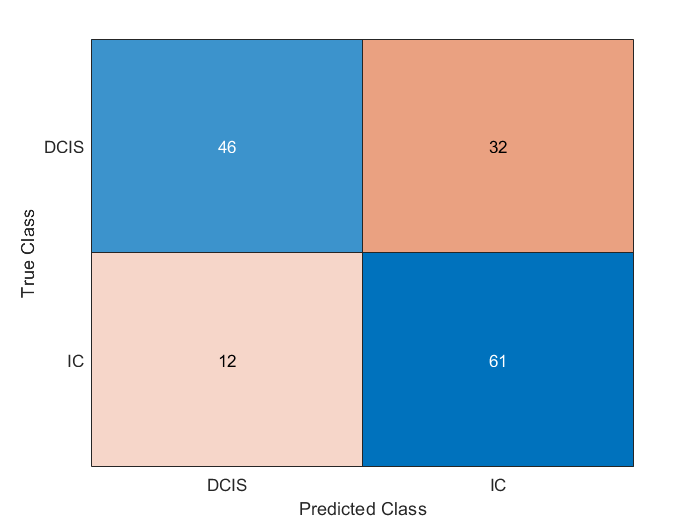

mdlNBLoss1 = kfoldLoss(mdlNB1, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlNB1);
confusionchart(data_todo.("Tipo de cáncer"),yFit)

## Discriminant linear

mdlDisAn = fitcdiscr(data1,"Tipo de cáncer","CVPartition",cvpt1)

mdlDisAn =   ClassificationPartitionedModel
    CrossValidatedModel: 'Discriminant'
         PredictorNames: {1×12 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 151
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [DCIS    IC]
         ScoreTransform: 'none'


  Properties, Methods


mdlDisAnLoss = kfoldLoss(mdlDisAn)

mdlDisAnLoss =    0.178807947019867


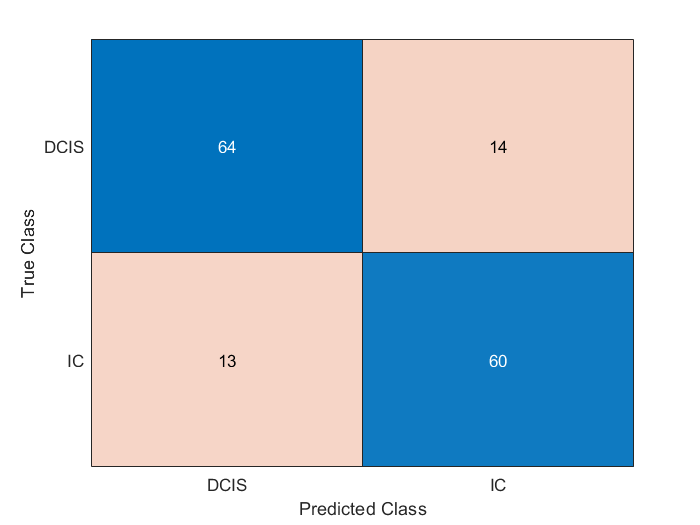

mdlDisAnLoss = kfoldLoss(mdlDisAn, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlDisAn);
confusionchart(data1.("Tipo de cáncer"),yFit)


mdlDisAn1 = fitcdiscr(data_todo,"Tipo de cáncer","CVPartition",cvpt2)

mdlDisAn1 =   ClassificationPartitionedModel
    CrossValidatedModel: 'Discriminant'
         PredictorNames: {1×16 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 151
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [DCIS    IC]
         ScoreTransform: 'none'


  Properties, Methods


mdlDisAnLoss1 = kfoldLoss(mdlDisAn1)

mdlDisAnLoss1 =    0.238410596026490


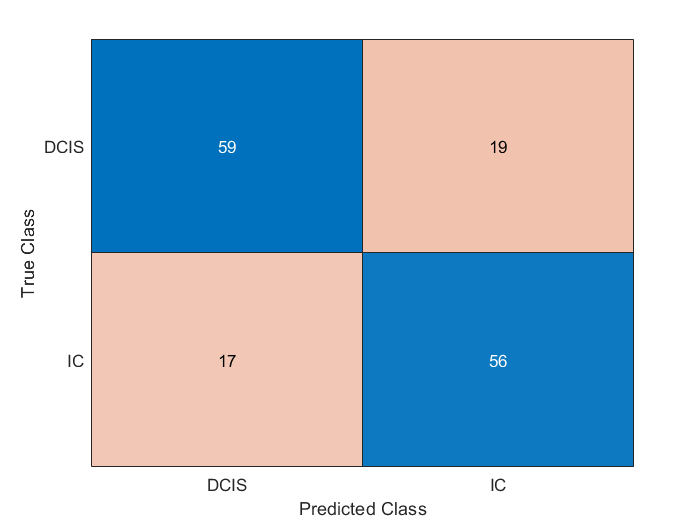

mdlDisAnLoss1 = kfoldLoss(mdlDisAn1, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlDisAn1);
confusionchart(data_todo.("Tipo de cáncer"),yFit)

## Discriminant quadratic

mdlDisAnQ = fitcdiscr(data1,"Tipo de cáncer","CVPartition",cvpt1, 'DiscrimType','quadratic')

mdlDisAnQ =   ClassificationPartitionedModel
    CrossValidatedModel: 'Discriminant'
         PredictorNames: {1×12 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 151
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [DCIS    IC]
         ScoreTransform: 'none'


  Properties, Methods


mdlDisAnLossQ = kfoldLoss(mdlDisAnQ)

mdlDisAnLossQ =    0.205298013245033


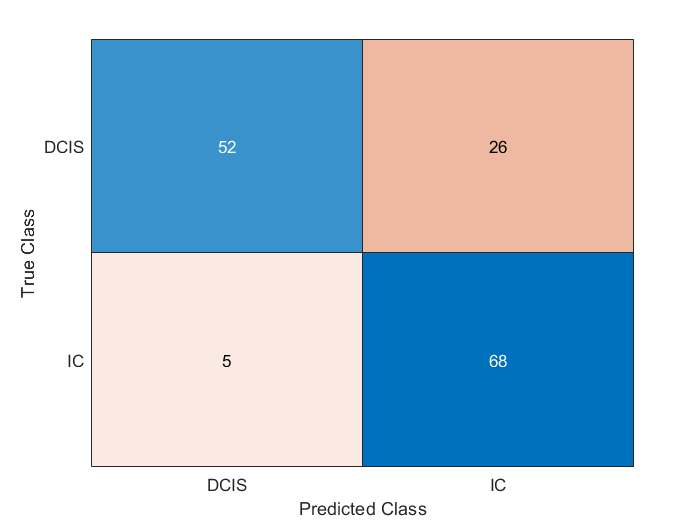

mdlDisAnLossQ = kfoldLoss(mdlDisAnQ, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlDisAnQ);
confusionchart(data1.("Tipo de cáncer"),yFit)


mdlDisAnQ1 = fitcdiscr(data_todo,"Tipo de cáncer","CVPartition",cvpt2,'DiscrimType','quadratic')

mdlDisAnQ1 =   ClassificationPartitionedModel
    CrossValidatedModel: 'Discriminant'
         PredictorNames: {1×16 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 151
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [DCIS    IC]
         ScoreTransform: 'none'


  Properties, Methods


mdlDisAnLossQ1 = kfoldLoss(mdlDisAnQ1)

mdlDisAnLossQ1 =    0.205298013245033


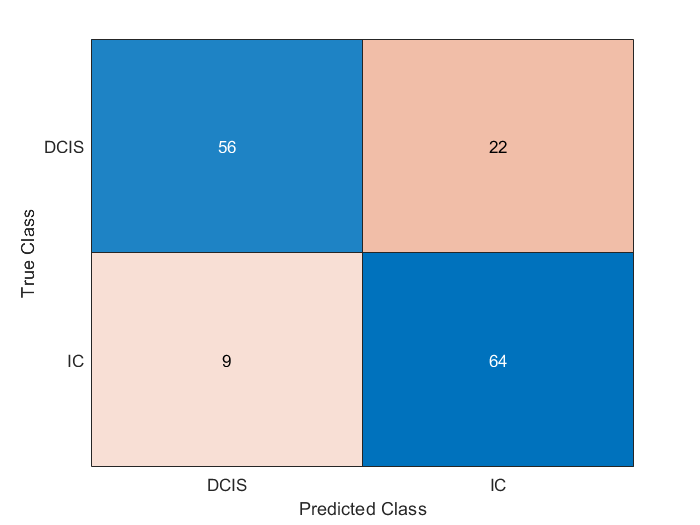

mdlDisAnLossQ1 = kfoldLoss(mdlDisAnQ1, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlDisAnQ1);
confusionchart(data_todo.("Tipo de cáncer"),yFit)

## SVM

mdlSvm = fitcsvm(data1, "Tipo de cáncer","CVPartition",cvpt1)

mdlSvm =   ClassificationPartitionedModel
    CrossValidatedModel: 'SVM'
         PredictorNames: {1×12 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 151
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [DCIS    IC]
         ScoreTransform: 'none'


  Properties, Methods


mdlSvmLoss = kfoldLoss(mdlSvm)

mdlSvmLoss =    0.198675496688742


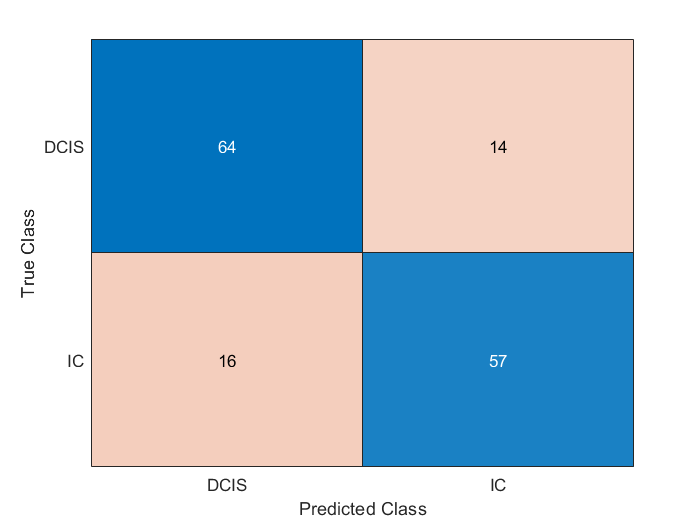

mdlSvmLoss = kfoldLoss(mdlSvm, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlSvm);
confusionchart(data1.("Tipo de cáncer"),yFit)


mdlSvm1 = fitcsvm(data_todo, "Tipo de cáncer","CVPartition",cvpt2)

mdlSvm1 =   ClassificationPartitionedModel
    CrossValidatedModel: 'SVM'
         PredictorNames: {1×16 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 151
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [DCIS    IC]
         ScoreTransform: 'none'


  Properties, Methods


mdlSvmLoss1 = kfoldLoss(mdlSvm1)

mdlSvmLoss1 =    0.198675496688742


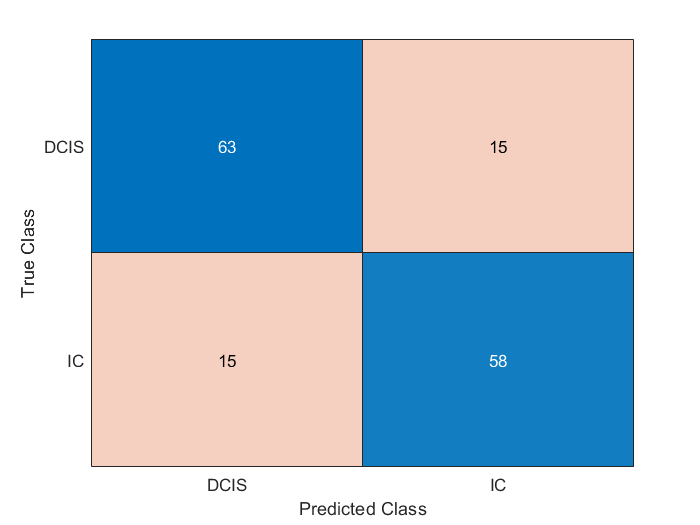

mdlSvmLoss1 = kfoldLoss(mdlSvm1, 'Mode', 'Individual');
[yFit1,sFit1] = kfoldPredict(mdlSvm1);
confusionchart(data_todo.("Tipo de cáncer"),yFit1)


mdlSvmQ = fitcsvm(data1, "Tipo de cáncer","CVPartition",cvpt1, 'KernelFunction', 'polynomial', 'PolynomialOrder',2)

mdlSvmQ =   ClassificationPartitionedModel
    CrossValidatedModel: 'SVM'
         PredictorNames: {1×12 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 151
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [DCIS    IC]
         ScoreTransform: 'none'


  Properties, Methods


mdlSvmLossQ = kfoldLoss(mdlSvmQ)

mdlSvmLossQ =    0.192052980132450


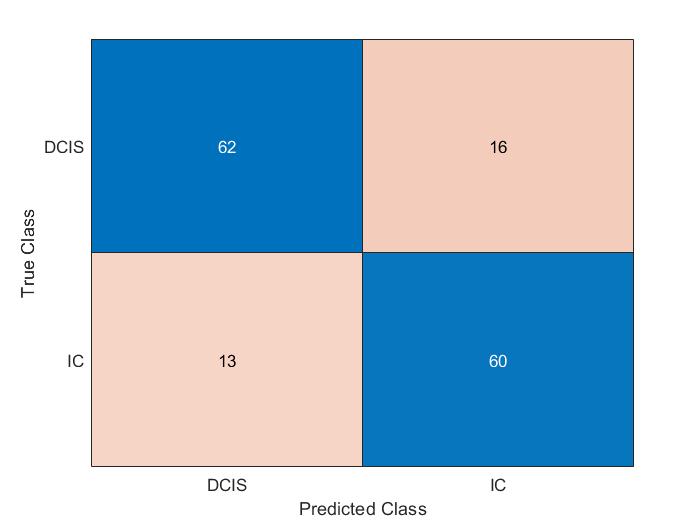

mdlSvmLossQ = kfoldLoss(mdlSvmQ, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlSvmQ);
confusionchart(data1.("Tipo de cáncer"),yFit)


mdlSvmQ1 = fitcsvm(data_todo, "Tipo de cáncer","CVPartition",cvpt2, 'KernelFunction', 'polynomial', 'PolynomialOrder',2)

mdlSvmQ1 =   ClassificationPartitionedModel
    CrossValidatedModel: 'SVM'
         PredictorNames: {1×16 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 151
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [DCIS    IC]
         ScoreTransform: 'none'


  Properties, Methods


mdlSvmLossQ1 = kfoldLoss(mdlSvmQ1)

mdlSvmLossQ1 =    0.218543046357616


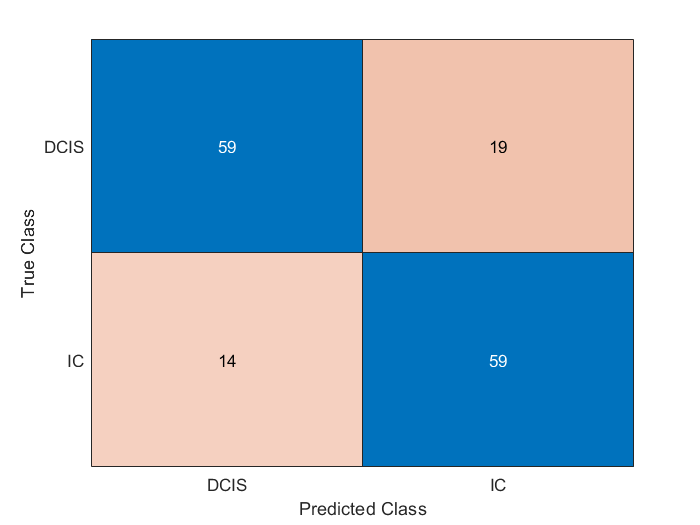

mdlSvmLossQ1 = kfoldLoss(mdlSvmQ1, 'Mode', 'Individual');
[yFit1,sFit1] = kfoldPredict(mdlSvmQ1);
confusionchart(data_todo.("Tipo de cáncer"),yFit1)

## Random forest

mdlRF = fitcensemble(data1, "Tipo de cáncer","CVPartition",cvpt1,"Method","Bag");
mdlRFLoss = kfoldLoss(mdlRF)

mdlRFLoss =    0.158940397350993


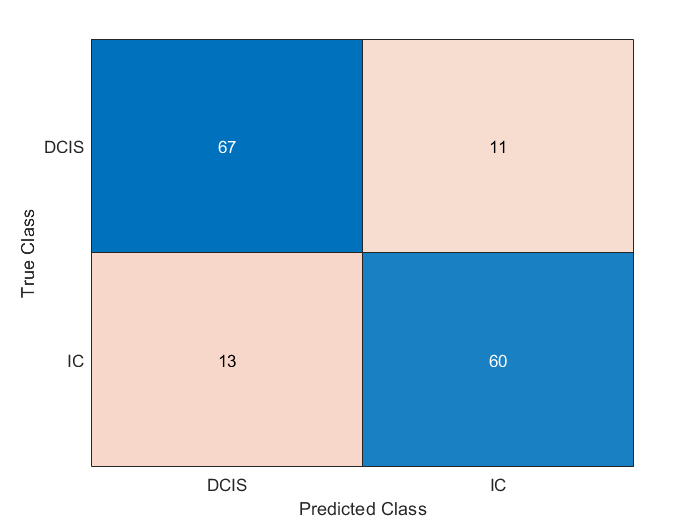

mdlRFLoss = kfoldLoss(mdlRF, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlRF);
confusionchart(data1.("Tipo de cáncer"),yFit)


mdlRF1 = fitcensemble(data_todo, "Tipo de cáncer","CVPartition",cvpt2,"Method","Bag");
mdlRFLoss1 = kfoldLoss(mdlRF1)

mdlRFLoss1 =    0.158940397350993


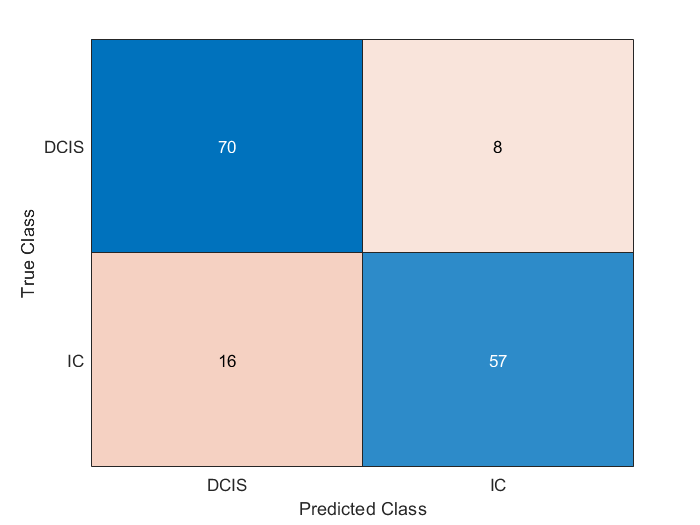

mdlRFLoss1 = kfoldLoss(mdlRF1, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlRF1);
confusionchart(data_todo.("Tipo de cáncer"),yFit)

## Ensemble cosas

lrns = {templateKNN("NumNeighbors",2), templateKNN("NumNeighbors",4)}

lrns = 1×2 cell array
    {1×1 classreg.learning.FitTemplate}    {1×1 classreg.learning.FitTemplate}


%final_mdl = fitcensemble(data_todo, "Tipo de cáncer","Learners",lnrs)
%lnrs = {templateDiscriminant("delta",3.2158e-05, "gamma",0.00049044 )}
mdlKnnEns = fitcensemble(data1, "Tipo de cáncer","Learners",lrns,"CVPartition",cvpt2)

mdlKnnEns =   ClassificationPartitionedEnsemble
    CrossValidatedModel: 'Subspace'
         PredictorNames: {1×12 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 151
                  KFold: 5
              Partition: [1×1 cvpartition]
      NumTrainedPerFold: [200 200 200 200 200]
             ClassNames: [DCIS    IC]
         ScoreTransform: 'none'


  Properties, Methods


mdlKnnEnsLoss = kfoldLoss(mdlKnnEns)

mdlKnnEnsLoss =    0.344370860927152


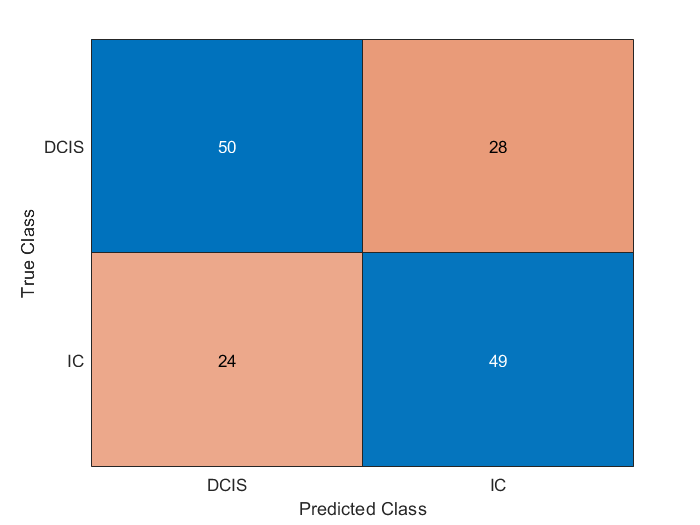

mdlKnnEnsLoss = kfoldLoss(mdlKnnEns, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlKnnEns);
confusionchart(data1.("Tipo de cáncer"),yFit)


mdlKnnEns1 = fitcensemble(data_todo, "Tipo de cáncer","Learners",lrns,"CVPartition",cvpt2)

mdlKnnEns1 =   ClassificationPartitionedEnsemble
    CrossValidatedModel: 'Subspace'
         PredictorNames: {1×16 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 151
                  KFold: 5
              Partition: [1×1 cvpartition]
      NumTrainedPerFold: [200 200 200 200 200]
             ClassNames: [DCIS    IC]
         ScoreTransform: 'none'


  Properties, Methods


mdlKnnEnsLoss1 = kfoldLoss(mdlKnnEns1)

mdlKnnEnsLoss1 =    0.337748344370861


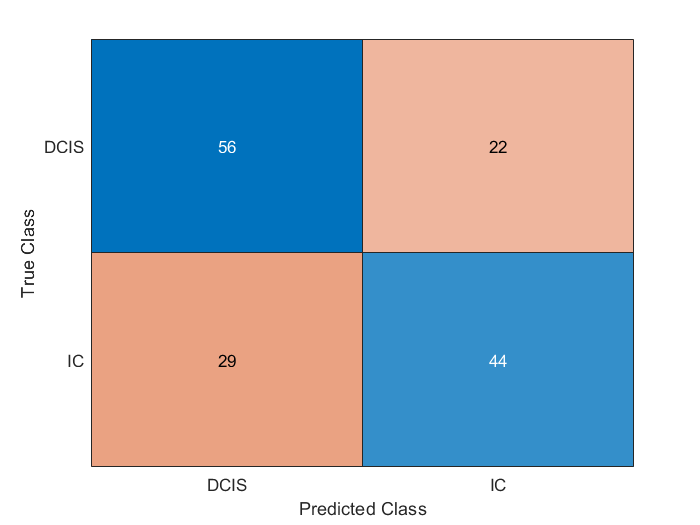

mdlKnnEnsLoss1 = kfoldLoss(mdlKnnEns1, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlKnnEns1);
confusionchart(data_todo.("Tipo de cáncer"),yFit)

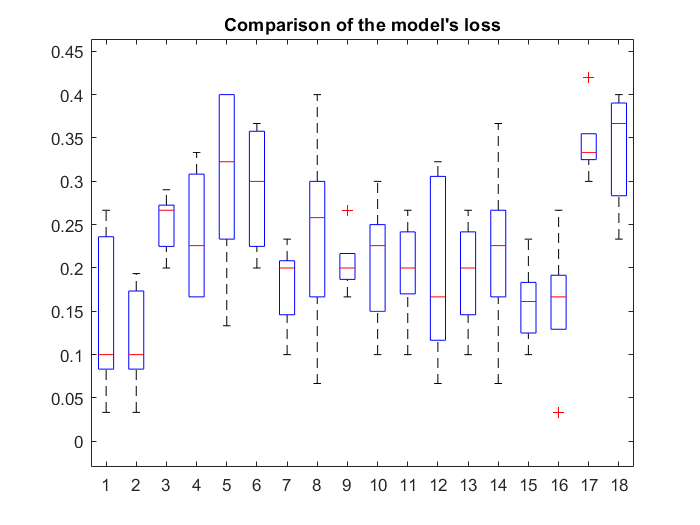

loss_matrix = [[mdlLoss],[mdlLoss1],[mdlTreeLoss],[mdlTreeLoss1], [mdlNBLoss],[mdlNBLoss1], [mdlDisAnLoss],[mdlDisAnLoss1],[mdlDisAnLossQ],[mdlDisAnLossQ1],[mdlSvmLoss],[mdlSvmLoss1],[mdlSvmLossQ],[mdlSvmLossQ1],[mdlRFLoss],[mdlRFLoss1],[mdlKnnEnsLoss],[mdlKnnEnsLoss1]];
boxplot(loss_matrix)
title("Comparison of the model's loss")

opts = delimitedTextImportOptions("NumVariables", 24);
% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";
% Specify column names and types
opts.VariableNames = ["Área", "Longitud eje mayor", "Longitud eje menor", "Área convexa","Circularidad", "Perímetro", "Distancia mínima entre núcleos", "Varianza área","Varianza área convexa","Varianza circularidad","Varianza perímetro","Varianza longitud eje mayor","Ratio medio distancia ejes","Porcentaje de núcleos","Varianza de la distancia del eje menor","Compactabilidad de núcleos","Distancia media entre núcleos","Varianza distancia entre núcleos","Varianza del ratio de distancia ejes","Contraste","Correlación", "Homogenidad","Energía","Tipo de cáncer"];
opts.VariableTypes = ["double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","categorical"];
% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
Av = struct2cell(load("5_DCISv.mat"));
Av = Av{1,1};
Bv = struct2cell(load("6_ICv.mat"));
Bv = Bv{1,1};

Taula = [Av; Bv];
% for i=1:23
%     dataN2(:,i)=array2table(rescale(table2array(dataN1(:,i))));
% end
% data_todo = dataN2;
Taulav = Taula;
for i=1:23
    Taulav(:,i)=array2table(rescale(table2array(Taula(:,i))));
end

TaulaV = processed(Taulav);
TaulaV(:, [1,4,6,9,11,21,22]) = [];

final_mdl = fitcknn(data_todo, "Tipo de cáncer","NumNeighbors",2, 'DistanceWeight', 'inverse');
%lrnrs = {templateKNN("NumNeighbors",4), templateDiscriminant, templateKNN("NumNeighbors", 2)}
%final_mdl = fitcensemble(data_todo, "Tipo de cáncer","Learners",lrnrs)

predictions = predict(final_mdl,TaulaV);
mdlLoss = loss(final_mdl,TaulaV)

mdlLoss =    0.366394251092011


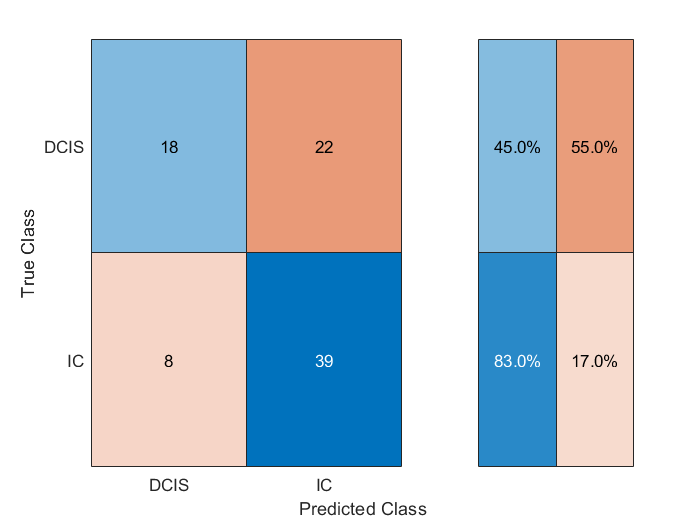

confusionchart(TaulaV.("Tipo de cáncer"),predictions,"RowSummary","row-normalized");

accuracy = sum(TaulaV.("Tipo de cáncer")==predictions)/numel(TaulaV.("Tipo de cáncer"))

accuracy =    0.655172413793103
